# Tensor contractions

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Here we will explain how to contract tensors in MATLAB. Consider three tensors A, B, and C:

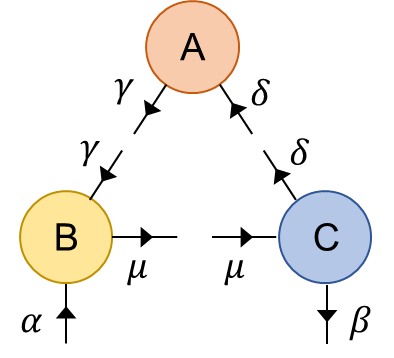

The legs with the same indices will be contracted. In this tutorial, we will treat the tensors as mere numerical arrays in which the directions of tensor legs are not important. Thus we will omit the arrows for the rest of this tutorial. Of course, when the tensors are in physical context (e.g., bras, kets) or non-Abelian symmetries are exploited (to be covered later in the lecture course), the leg directions do matter!

## Initialization

Clear workspace (clear pre-existing variables to avoid any collision), and set the leg dimensions to determine the size of tensors. Leg dimensions are also often called bond dimensions when the corresponding legs are from different tensors and to be contracted to "bond" tensors.

clear

% leg dimensions
d_a = 101; % d_alpha
d_b = 102; % d_beta
d_c = 103; % d_gamma
d_d = 104; % d_delta
d_m = 105; % d_mu

Then generate rank-2 tensor `A` (of size d_c-by-d_d) and rank-3 tensors `B` (of size d_a-by-d_m-by-d_c) and `C` (of size d_b-by-d_m-by-d_d) with random elements.

A = rand(d_c,d_d);     % tensor A(gamma,delta)
B = rand(d_a,d_m,d_c); % tensor B(alpha,mu,gamma)
C = rand(d_b,d_m,d_d); % tensor C(beta,mu,delta)

Initiate timers for real/CPU tiume.

tobj = tic2;

## Contract B and C

Let's contract B and C first. Bring the rank-3 tensor B into a matrix from, by permuting its legs and by reshaping, as depicted by the following diagram:

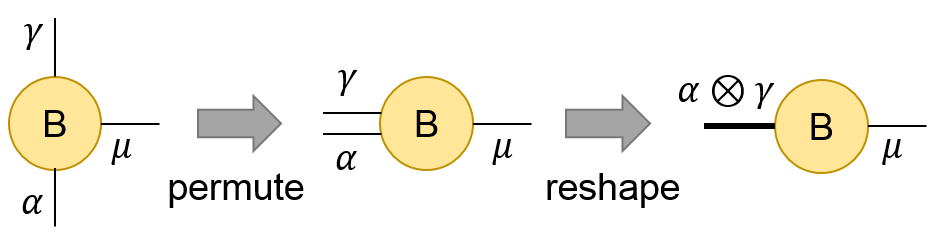

Here the thick leg means that the associated leg dimension is big, since two legs are combined by `reshape`.

B1 = permute(B,[1,3,2]); % B(alpha,mu,gamma) -> B(alpha,gamma,mu)
B1 = reshape(B1,[d_a*d_c,d_m]); % B(alpha,gamma,mu) -> B(alpha*gamma,mu)

Treat tensor C similarly.

C1 = permute(C,[2,1,3]); % C(beta,mu,delta) -> C(mu,beta,delta)
C1 = reshape(C1,[d_m,d_b*d_d]); % C(mu,beta,delta) -> C(mu;beta*delta)

The reshaped `B` and `C` (numerically represented by `B1` and `C1`) are matrices (i.e., rank-2 tensors), so the legs can be contracted via matrix multiplication. As mentioned in the previous tutorial, MATLAB is very efficient when it performs linear algebra operations. Let's contract `B1` and `C1` via their $\mu$-legs, and separate the combined $\alpha \otimes \gamma$- and $\delta \otimes \beta$-legs into four legs $\alpha ,\beta ,\gamma ,\delta$, as below.

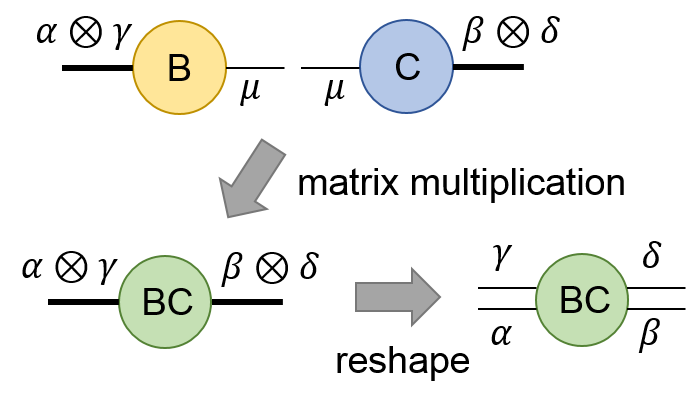

BC = B1*C1;% \sum_{mu} B(alpha*gamma,mu) * C(mu,beta*delta) 
           % = BC(alpha*gamma,beta,delta)
% BC(alpha*gamma,beta*delta) -> BC(alpha,gamma,beta,delta)
BC = reshape(BC,[d_a,d_c,d_b,d_d]);

## Contract BC and A

The remaining tensors look like:

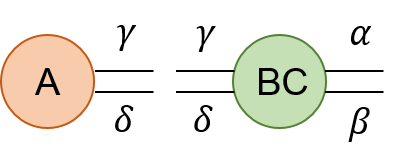

Bring `BC` into a matrix from by using `permute` and `reshape`.

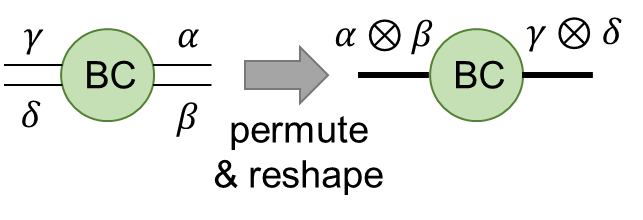

% BC(alpha,gamma,beta,delta) -> BC(alpha,beta,gamma,delta)
BC = permute(BC,[1,3,2,4]);
% BC(alpha,beta,gamma,delta) -> BC(alpha*beta;gamma*delta)
BC = reshape(BC,[d_a*d_b,d_c*d_d]);

Then reshape tensor `A` into a vector (though it's treated as a "thin" matrix in MATLAB) and multiply it with `BC`. By reshaping `ABC` into rank-2 tensor, we have rank-2 tensor `ABC`.

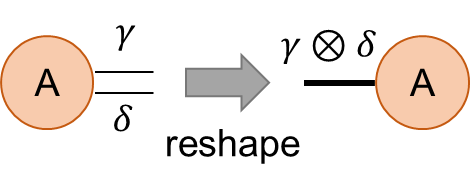

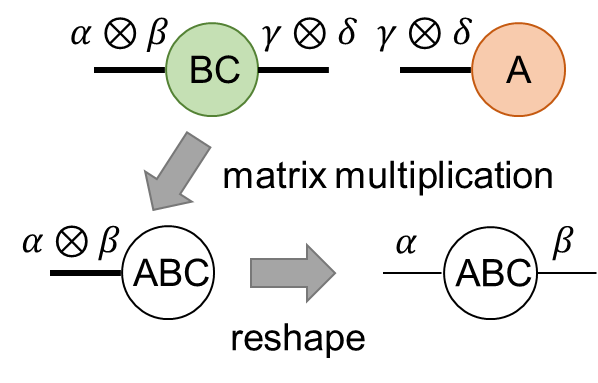

A1 = A(:);   % A(gamma,delta) -> A(gamma*delta)
% \sum_{gamma,delta} BC(alpha*beta,gamma*delta) * A(gamma*delta) 
%       = ABC(alpha,beta)
ABC1 = BC*A1;              
ABC1 = reshape(ABC1,[d_a,d_b]);% ABC(alpha*beta) -> ABC(alpha,beta)

How much time has been taken?

toc2(tobj,'-v');

Elapsed time: 0.394s, CPU time: 3.26s, Avg # of cores: 8.273


Usually CPU time lapse is several times larger than real time lapse. It shows that MATLAB automatically parallelized computation.

## Short remark: Why do we use matrix multiplication, instead of for-loops?

One may ask why we bother with reshaping and permuting tensors. So let's compare the computational costs between two approaches. First, below is the part of the above code contracting `B` and `C`.

% % Scheme 1: Tensor contraction using matrix multiplication
tobj = tic2;

B1 = permute(B,[1,3,2]); % B(alpha,mu,gamma) -> B(alpha,gamma,mu)
B1 = reshape(B1,[d_a*d_c,d_m]);% B(alpha,gamma,mu) -> B(alpha*gamma,mu)
C1 = permute(C,[2,1,3]); % C(beta,mu,delta) -> C(mu,beta,delta)
C1 = reshape(C1,[d_m,d_b*d_d]);% C(mu,beta,delta) -> C(mu,beta*delta)
% \sum_{mu} B(alpha*gamma,mu) * C(mu,beta*delta)
%      = BC(alpha*gamma,beta*delta)
BC = B1*C1;              
% BC(alpha*gamma,beta*delta) -> BC(alpha,gamma,beta,delta)
BC = reshape(BC,[d_a,d_c,d_b,d_d]);

toc2(tobj,'-v');

Elapsed time: 0.2529s, CPU time: 1.88s, Avg # of cores: 7.433


Second, this is a contraction using for-loops. (If it takes too long and your laptop suffers, press Ctrl+C or click "Stop" (red square button) on the top.)

% % Scheme 2: Tensor contraction using for-loops
tobj = tic2;

% create an 4D-array initialized with zeros
BC = zeros(d_a,d_c,d_b,d_d);
for it1 = (1:size(BC,1)) % alpha
    for it2 = (1:size(BC,2)) % gamma
        for it3 = (1:size(BC,3)) % beta
            for it4 = (1:size(BC,4)) % delta
                for it5 = (1:size(B,2)) % mu
                    BC(it1,it2,it3,it4) = ...
                        BC(it1,it2,it3,it4) + ...
                        B(it1,it5,it2)*C(it3,it5,it4);
                end
            end
        end
    end
end

toc2(tobj,'-v');

Elapsed time: 101.4s, CPU time: 107.8s, Avg # of cores: 1.064


We see that the latter scheme takes much longer time (about 100 times)! (**Note:** actual ratio of CPU times may depend on many factors, such as the randomness in tensor initialization, MATLAB version, CPU architecture, etc.)

In MATLAB, matrix operation is much faster than for-loops, since MATLAB implements a state-of-the-art linear algebra algorithm which is better parallelizable, for example. Try to avoid use for-loops for matrix or tensor operations as much as possible!

## Exercise (a): First contract A and C, and then contract AC and B

Try a different order of the tensor contraction. Contract A and C first, then contract B, as a diagram below.

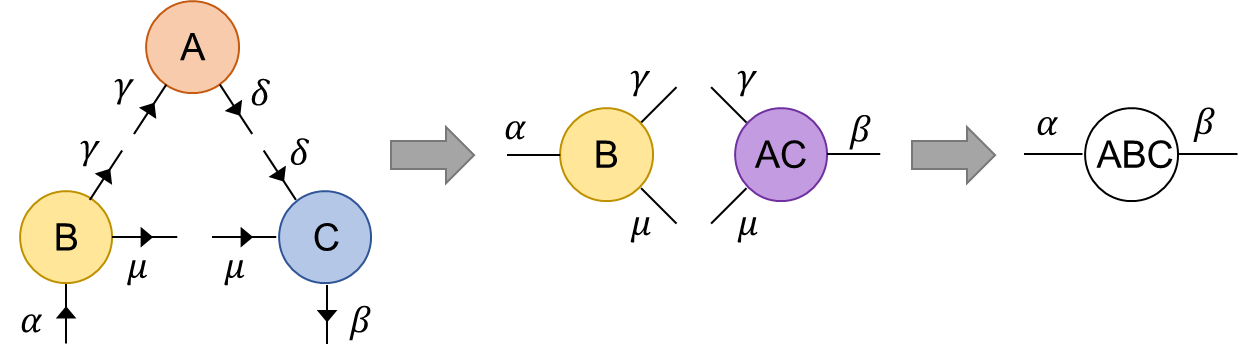

Write a script which implements this way of tensor contraction, and compare the computational costs in terms of both real time and CPU time. Which one is faster, by which factor?